# **Proyecto Final - Codificación Lineal Predictiva**

**Martin Felipe Bermudez Romero - 20201005164**

**Nicolás José Garzon Pacheco - 20201005054**

**Universidad Distrital Francisco Jose de Caldas**

**Procesamiento Digital de Señales**

## Resumen

En esta práctica se explora el modelado paramétrico de señales, enfocándose en el tracto vocal como un filtro lineal de solo polos. Los parámetros del modelo se estiman mediante optimización, y el filtro resultante predice cada muestra de la señal como una combinación lineal de las muestras anteriores, generando un filtro predictor cuyos coeficientes representan los parámetros de la Codificación Lineal Predictiva (LPC) de señales de voz.

## Introducción

El modelado paramétrico de señales busca simplificar procesos complejos con múltiples variables mediante la estimación de pocos parámetros a partir de las señales generadas por dicho proceso. Este enfoque permite una alta compresión de datos y se aplica en diversas áreas como economía, control, telecomunicaciones y procesamiento de señales. Aunque la reducción implica una aproximación, la significancia física de los parámetros ofrece una comprensión del comportamiento general del proceso.

El proceso de modelado paramétrico implica elegir una forma paramétrica adecuada para el modelo, seguida de la determinación de los parámetros que mejor aproximen la señal, lo cual se logra mediante la resolución de un problema de optimización. En este contexto, se elige un modelo lineal para la señal de voz y se estiman los parámetros del modelo, específicamente los coeficientes del filtro. Estos parámetros se emplean posteriormente en aplicaciones como reconocimiento de voz e identificación de parámetros, demostrando la potencia del modelado paramétrico. La introducción revisa los conceptos estudiados previamente, destacando la relevancia y versatilidad de este enfoque.

**Modelos Lineales invariantes en el tiempo:**

Los modelos lineales invariantes en el tiempo (LTI) son una clase de modelos matemáticos que describen sistemas cuya respuesta a una entrada no depende del tiempo en que se aplica. Estos modelos se utilizan ampliamente en el procesamiento de señales para representar sistemas como filtros, ecualizadores y sistemas de control.

**Modelo de producción de la señal de voz:**

La señal de voz se produce cuando el aire vibra en las cuerdas vocales y pasa a través de la cavidad oral y nasal. La forma de estas cavidades modifica el sonido, creando las diferentes vocales y consonantes.

**Estimación de los parámetros del modelo:**

La estimación de los parámetros del modelo se realiza mediante un proceso de optimización que busca minimizar el error entre la señal real y la señal predicha por el modelo. Existen diferentes métodos de optimización, como el método de mínimos cuadrados o el método de descenso de gradiente.

## Planteamiento del Problema

En el desarrollo de esta experiencia de laboratorio, es esencial establecer diversos parámetros como ventanas, filtros, períodos y frecuencias, entre otros, para identificar y categorizar los fonemas presentes en las señales de voz. Estos fonemas se manifiestan en instantes pseudo-periódicos, lo que permite extraer información crucial, como las componentes espectrales y los patrones inherentes en la señal auditiva. La práctica experimental se divide en dos segmentos, cada uno abordando aspectos particulares:

**Primera Parte: Análisis de Formantes**

En este ejercicio, se propone utilizar un filtro lineal predictivo para representar la cavidad oral, donde los polos del filtro se corresponden con los formantes, es decir, las frecuencias de resonancia de la cavidad oral. Estos formantes se visualizan como picos en la respuesta en frecuencia.

**Construcción del espectrograma:**

Al graficar la respuesta en frecuencia para segmentos pseudo-estacionarios de la señal de voz, mediante el uso de una ventana Hamming desplazada a lo largo de la señal, se construiría un espectrograma que muestra la respuesta espectral del filtro de la cavidad oral en lugar del contenido espectral de la señal de voz.

**Observación de la trayectoria de los formantes:**

La trayectoria de los formantes se puede seguir observando el desplazamiento de los picos en la frecuencia a lo largo del tiempo en este espectrograma. Para lograr una transición suave entre fonemas y una observación clara de los formantes, se propone grabar una secuencia de fonemas /AEIUO/ con pronunciación lenta y continua.

**Consideraciones para la detección de formantes:**

- **Tamaño de la ventana Hamming:** Es crucial seleccionar adecuadamente el tamaño de la ventana Hamming para una detección "suficientemente precisa" de los formantes.

- **Filtro de pre-énfasis:** Se sugiere utilizar un filtro de pre-énfasis antes de visualizar los formantes, amplificando las altas frecuencias en la señal de voz para mejorar la claridad en el espectrograma de la respuesta en frecuencia de la cavidad oral (por ejemplo, mediante la expresión y[n] = x[n] – 0.625x[n-1]).

**Segunda Parte: Reconocimiento de Vocales.**

La información en la envolvente espectral:

La posibilidad de identificar una vocal sin escucharla, simplemente observando su envolvente espectral, se plantea como un fenómeno intrigante. Además, se sugiere que, con suficiente práctica, uno podría incluso llegar a identificar a la persona que pronunció una vocal específica, en este caso, la vocal /A/, únicamente a través de la observación de su envolvente espectral.

**Explicación del fenómeno:**

Este fenómeno interesante se explica por la capacidad de los coeficientes predictores, que codifican la forma del tracto vocal durante la pronunciación de cada fonema. Dado que cada persona tiene una forma particular de articular cada fonema, los coeficientes predictores retienen información suficiente para reconocer el fonema específico pronunciado. Además, la respuesta en frecuencia del tracto vocal varía según las dimensiones y otras características únicas de cada individuo, lo que implica que los coeficientes predictores también contienen información sobre la identidad de la persona que habla.

**Diseño de la aplicación:**

En la segunda parte del ejercicio, se propone diseñar e implementar una aplicación de reconocimiento de vocales basada en los coeficientes predictores. Esta aplicación utilizará un micrófono para detectar cuando alguien pronuncia una vocal y mostrará en la pantalla la vocal pronunciada.

**Reconocimiento de la vocal /A:**

Además, si la vocal es /A/, la aplicación deberá ser capaz de determinar si la persona que la pronunció es una mujer o un hombre. Este reconocimiento se basará en las características distintivas de la envolvente espectral de la vocal /A/ pronunciada por hombres y mujeres.

**Consideraciones para el diseño:**

- **Extracción de características:** Se deben extraer características relevantes de la envolvente espectral de la vocal /A/ para diferenciar entre hombres y mujeres.

- **Clasificación:** Se debe utilizar un algoritmo de clasificación para identificar el género a partir de las características extraídas.

- **Interfaz de usuario:** La aplicación debe tener una interfaz de usuario intuitiva que permita interactuar con el micrófono y visualizar los resultados del reconocimiento.

**IV. Desarrollo**

**Lectura masculino**

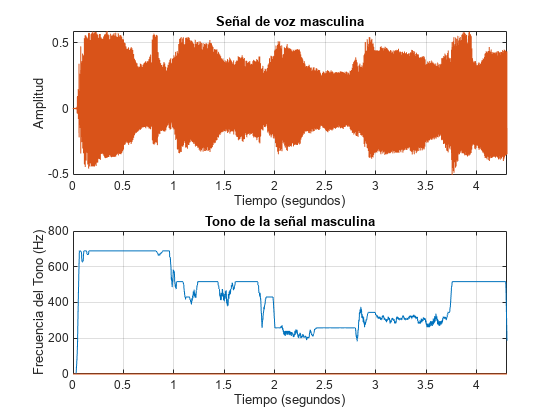

fs=44100;
% Lectura de audio desde 0.5 segundos hasta 5.5 segundos
[x, fs] = audioread('audiom.wav',[0.45,4.75]*fs);

% Parámetros de la señal de audio
t = (0:1/fs:(length(x)-1)*1/fs)';
L = length(x);

% Parámetros de la STFT (Transformada de Fourier de Tiempo Corto)
WS = 512;                                           % Tamaño de la ventana de análisis (512 muestras)
DW = 64;                                            % Desplazamiento entre ventanas (64 muestras)
NW = floor((L-WS)/DW) + 1;                          % Número total de ventanas
g = 0.54 + 0.46*cos(2*pi*(0:WS-1)'/WS - pi);        % Ventana de Hamming

X = zeros(WS/2, NW);                                % Matriz para almacenar espectros de frecuencia

% Cálculo del espectro de frecuencia para cada ventana
for k = 1:NW
    n = DW*(k-1) + (1:WS)';
    y = x(n) .* g';
    Y = fft(y);
    X(:, k) = 20 .* log10(abs(Y(1:WS/2)));          % Calculamos el máximo para esta ventana
end

% Inicialización de variables para detección de tono
tone = zeros(size(x));

% Detección de tono en cada ventana
for k = 1:NW
    n = DW*(k-1) + (1:DW)';
    y = x(n) .* g';
    Y = fft(y);
    F = (fs * (0:WS/2-1) / WS);                         % Frecuencias correspondientes a la mitad del espectro
    Fc = 700;                                           % Frecuencia máxima deseada
    IxFc = find(F >= Fc - F(2)/2 & F <= Fc + F(2)/2);   % Índice de esta frecuencia
    [A, IndxA] = max(X(1:IxFc, k));
    
    % Si el máximo está por debajo de -25 dB, se considera sin tono
    if A < -25
        tone(DW*(k-1) + (1:DW)) = 0;
    else
        tone(DW*(k-1) + (1:DW)) = F(IndxA);         % Frecuencia del máximo
    end
end

% Filtro pasa bajos para suavizar la señal de tono
wz = 800;
b = (1/wz) * ones(1, wz);
a = 1;
tonos = filter(b, a, tone);

% Visualización de resultados
figure;
title("Masculina")
subplot(2, 1, 1), plot(t, x)
title("Señal de voz masculina");
xlabel("Tiempo (segundos)")
ylabel("Amplitud")
xlim([0,4.3])
grid on

subplot(2, 1, 2), plot(t, tonos)
title("Tono de la señal masculina");
xlabel("Tiempo (segundos)")
ylabel("Frecuencia del Tono (Hz)")
xlim([0,4.3])
grid on

Esta parte del código analiza una muestra de voz masculina en términos de su contenido de frecuencia y muestra tanto la forma de onda original como la frecuencia del tono detectado en la señal.

**Audio Femenino**

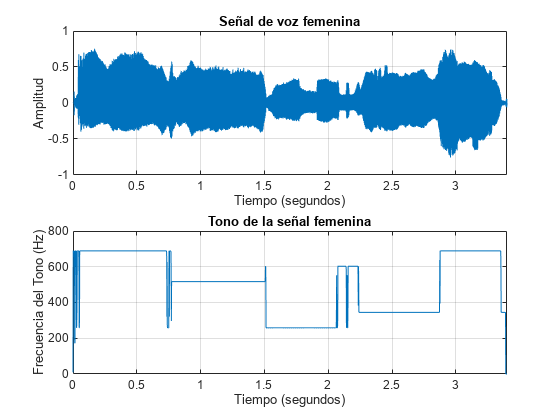

% Lectura de audio desde 0.5 segundos hasta 5.5 segundos
[x, fs] = audioread('audiof.wav',[0.8 , 4.2]* fs);

% Parámetros de la señal de audio
t = (0:1/fs:(length(x)-1)*1/fs)';
L = length(x);

% Parámetros de la STFT (Transformada de Fourier de Tiempo Corto)
WS = 512;                                           % Tamaño de la ventana de análisis (512 muestras)
DW = 64;                                            % Desplazamiento entre ventanas (64 muestras)
NW = floor((L-WS)/DW) + 1;                          % Número total de ventanas
g = 0.54 + 0.46*cos(2*pi*(0:WS-1)'/WS - pi);        % Ventana de Hamming

X = zeros(WS/2, NW);                                % Matriz para almacenar espectros de frecuencia

% Cálculo del espectro de frecuencia para cada ventana
for k = 1:NW
    n = DW*(k-1) + (1:WS)';
    y = x(n) .* g';
    Y = fft(y);
    X(:, k) = 20 .* log10(abs(Y(1:WS/2)));          % Calculamos el máximo para esta ventana
end

% Inicialización de variables para detección de tono
tone = zeros(size(x));

% Detección de tono en cada ventana
for k = 1:NW
    n = DW*(k-1) + (1:DW)';
    y = x(n) .* g';
    Y = fft(y);
    F = (fs * (0:WS/2-1) / WS);                         % Frecuencias correspondientes a la mitad del espectro
    Fc = 700;                                           % Frecuencia máxima deseada
    IxFc = find(F >= Fc - F(2)/2 & F <= Fc + F(2)/2);   % Índice de esta frecuencia
    [A, IndxA] = max(X(1:IxFc, k));
    
    % Si el máximo está por debajo de -25 dB, se considera sin tono
    if A < -25
        tone(DW*(k-1) + (1:DW)) = 0;
    else
        tone(DW*(k-1) + (1:DW)) = F(IndxA);         % Frecuencia del máximo
    end
end

% Filtro pasa bajos para suavizar la señal de tono
wz = 75;
b = (1/wz) * ones(1, wz);
a = 1;
tonos = filter(b, a, tone);

% Visualización de resultados
figure;
title("Masculina")
subplot(2, 1, 1), plot(t, x)
xlim([0,3.4])
title("Señal de voz femenina");
xlabel("Tiempo (segundos)")
ylabel("Amplitud")
grid on

subplot(2, 1, 2), plot(t, tonos)
xlim([0,3.4])
title("Tono de la señal femenina");
xlabel("Tiempo (segundos)")
ylabel("Frecuencia del Tono (Hz)")
grid on

  % Ejecuta las dos imagenes de las 2 señales de voz

Este código realiza un análisis similar al anterior en una señal de voz femenina.

**Ventana de Hamming para cada vocal **

**Vocal A**

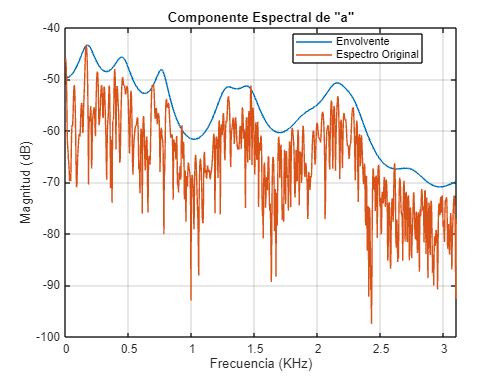

% Lectura del archivo de audio y re-muestreo
[audio, fs] = audioread('audiom.wav');
fs2 = 8000;
audio = resample(audio, fs2, fs);

% Definición de posiciones para las vocales en la señal de audio
a = 0;
e = 1 * fs2;
i = 2 * fs2;
u = 3 * fs2;
o = 3.75 * fs2;

% Tamaño de la ventana y aplicación de la ventana de Hamming a segmentos de audio
W_S = 1024;
xa = audio(a + (1:W_S)') .* hamming(W_S);
xe = audio(e + (1:W_S)') .* hamming(W_S);
xi = audio(i + (1:W_S)') .* hamming(W_S);
xu = audio(o + (1:W_S)') .* hamming(W_S);
xo = audio(u + (1:W_S)') .* hamming(W_S);

% Orden del modelo AR (Auto-regressive)
p = 20;
r = zeros(p + 1, 1);

% Cálculo de los coeficientes AR mediante la autocorrelación
for k = 0:p
    r(k + 1) = xa(1:(W_S - k))' * xa((k + 1):W_S);
end

R = r(1:p);
r = r(2:p + 1);

% Construcción de la matriz de coeficientes R y resolución del sistema lineal
for k = 2:p
    R(:, k) = [R(k, 1); R(1:p - 1, k - 1)];
end
Q = -inv(R) * r;

% Cálculo de la FFT de la señal de la vocal "a" y respuesta en frecuencia del modelo AR
X = fft(xa, 2048);
X = abs(X(1:1024));

[H, w] = freqz(1, [1; Q], 1024);

% Normalización y conversión a escala logarítmica (dB)
b0 = max(abs(X)) / max(abs(H));
X = 20 * log10(abs(X));
H = 20 * log10(abs(b0 * H));

% Visualización del espectro de la vocal "a" y la respuesta en frecuencia del modelo AR
figure
plot(w, H, 'DisplayName', 'Envolvente'); 
hold on
grid on
plot(w, X, 'DisplayName', 'Espectro Original'); 
xlabel('Frecuencia (KHz)', 'DisplayName', 'Envolvente')
ylabel('Magnitud (dB)', 'DisplayName', 'Espectro Original')
xlim([0, 3.1]);
title('Componente Espectral de "a"')
legend('Location','best')

Esta parte del código modela la señal de la vocal "a" utilizando un modelo autorregresivo y muestra tanto su espectro original como la respuesta en frecuencia del modelo AR para analizar cómo se aproxima el modelo a la señal real en términos de su contenido espectral.

**Vocal E**

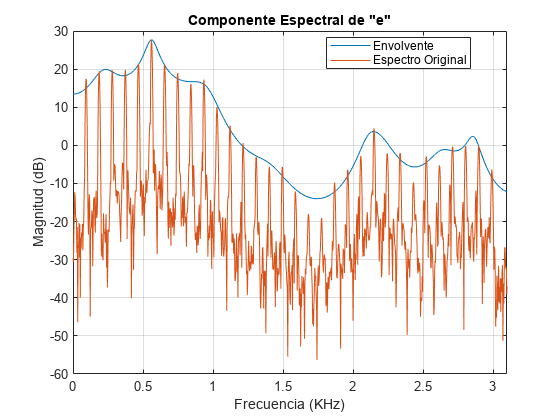

% Inicialización de variables
for k = 0:p
    % Calcula los productos internos entre segmentos de la señal xe
    r(k+1) = xe(1:(W_S-k))' * xe((k+1):W_S);
end

% Selección de segmentos de interés
R = r(1:p);
r = r(2:p+1);

% Construcción de la matriz R
for k = 2:p
    R(:, k) = [R(k, 1); R(1:p-1, k-1)];
end

% Resolución del sistema de ecuaciones para encontrar el filtro Q
Q = -inv(R) * r;

% Transformada de Fourier de la señal xe
X = fft(xe, 2048);
X = abs(X(1:1024));

% Cálculo de la respuesta en frecuencia del filtro
[H, w] = freqz(1, [1; Q], 1024);

% Normalización de la magnitud para ajuste en la gráfica
b0 = max(abs(X)) / max(abs(H));

% Cálculo de las magnitudes en dB
X = 20 * log10(abs(X));
H = 20 * log10(abs(b0 * H));

% Gráfica de la respuesta en frecuencia
figure
plot(w, H, 'DisplayName', 'Envolvente'); 
hold on
grid on
plot(w, X, 'DisplayName', 'Espectro Original'); 
xlabel('Frecuencia (KHz)')
ylabel('Magnitud (dB)')
title('Componente Espectral de "e"')

% Agregar leyendas
legend('Location', 'Best')

xlim([0, 3.1]);

Esta parte del código realiza un análisis similar al realizado para la vocal "a", pero ahora se enfoca en la vocal "e", modelando su comportamiento mediante un filtro AR y comparando su espectro original con la respuesta en frecuencia del modelo. Y de esta misma manera con las vocales "i", "o" y "u"

**Vocal I**

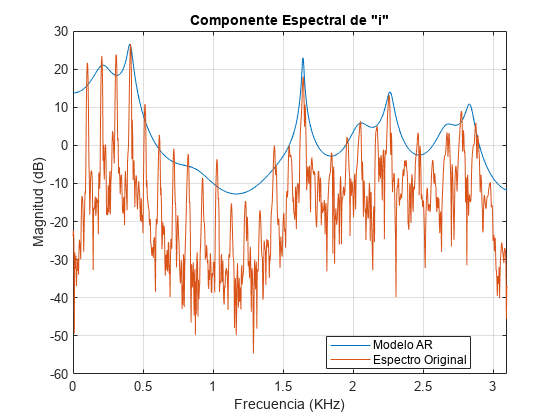

% Cálculo del modelo AR y visualización del espectro para la vocal "i"

% Inicialización de variables
for k = 0:p
    % Calcula los productos internos entre segmentos de la señal xi
    r(k+1) = xi(1:(W_S-k))' * xi((k+1):W_S);
end

% Selección de segmentos de interés
R = r(1:p);
r = r(2:p+1);

% Construcción de la matriz R
for k = 2:p
    R(:, k) = [R(k, 1); R(1:p-1, k-1)];
end

% Resolución del sistema de ecuaciones para encontrar el filtro Q
Q = -inv(R) * r;

% Transformada de Fourier de la señal xi
X = fft(xi, 2048);
X = abs(X(1:1024));

% Cálculo de la respuesta en frecuencia del filtro
[H, w] = freqz(1, [1; Q], 1024);

% Normalización de la magnitud para ajuste en la gráfica
b0 = max(abs(X)) / max(abs(H));

% Cálculo de las magnitudes en dB
X = 20 * log10(abs(X));
H = 20 * log10(abs(b0 * H));

% Gráfica de la respuesta en frecuencia
figure
plot(w, H, 'DisplayName', 'Modelo AR');
hold on
grid on
plot(w, X, 'DisplayName', 'Espectro Original');
xlabel('Frecuencia (KHz)')
ylabel('Magnitud (dB)')
title('Componente Espectral de "i"')

xlim([0, 3.1]);
% Agregar leyendas
legend('Location', 'Best')

**Vocal O**

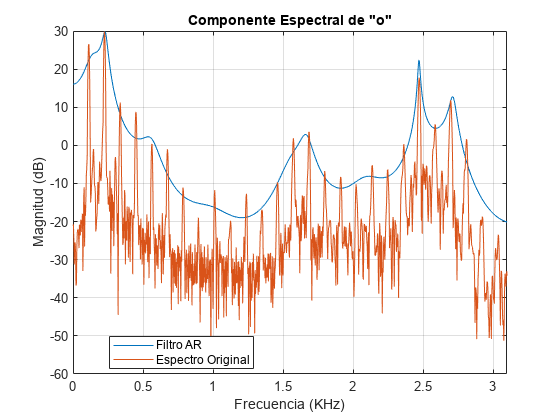

% Inicialización de variables
for k = 0:p
    % Calcula los productos internos entre segmentos de la señal xo
    r(k+1) = xo(1:(W_S-k))' * xo((k+1):W_S);
end

% Selección de segmentos de interés
R = r(1:p);
r = r(2:p+1);

% Construcción de la matriz R
for k = 2:p
    R(:, k) = [R(k, 1); R(1:p-1, k-1)];
end

% Resolución del sistema de ecuaciones para encontrar el filtro Q
Q = -inv(R) * r;

% Transformada de Fourier de la señal xo
X = fft(xo, 2048);
X = abs(X(1:1024));

% Cálculo de la respuesta en frecuencia del filtro
[H, w] = freqz(1, [1; Q], 1024);

% Normalización de la magnitud para ajuste en la gráfica
b0 = max(abs(X)) / max(abs(H));

% Cálculo de las magnitudes en dB
X = 20 * log10(abs(X));
H = 20 * log10(abs(b0 * H));

% Gráfica de la respuesta en frecuencia
figure
plot(w, H, 'DisplayName', 'Filtro AR');
hold on
grid on
plot(w, X, 'DisplayName', 'Espectro Original');
xlabel('Frecuencia (KHz)')
ylabel('Magnitud (dB)')
title('Componente Espectral de "o"')

xlim([0, 3.1]);
% Agregar leyendas
legend('Location', 'Best')

**Vocal U**

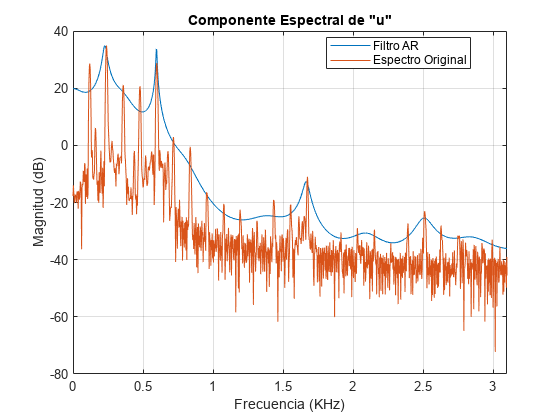

% Inicialización de variables
for k = 0:p
    % Calcula los productos internos entre segmentos de la señal xu
    r(k+1) = xu(1:(W_S-k))' * xu((k+1):W_S);
end

% Selección de segmentos de interés
R = r(1:p);
r = r(2:p+1);

% Construcción de la matriz R
for k = 2:p
    R(:, k) = [R(k, 1); R(1:p-1, k-1)];
end

% Resolución del sistema de ecuaciones para encontrar el filtro Q
Q = -inv(R) * r;

% Transformada de Fourier de la señal xu
X = fft(xu, 2048);
X = abs(X(1:1024));

% Cálculo de la respuesta en frecuencia del filtro
[H, w] = freqz(1, [1; Q], 1024);

% Normalización de la magnitud para ajuste en la gráfica
b0 = max(abs(X)) / max(abs(H));

% Cálculo de las magnitudes en dB
X = 20 * log10(abs(X));
H = 20 * log10(abs(b0 * H));

% Gráfica de la respuesta en frecuencia
figure
plot(w, H, 'DisplayName', 'Filtro AR');
hold on
grid on
plot(w, X, 'DisplayName', 'Espectro Original');
xlabel('Frecuencia (KHz)')
ylabel('Magnitud (dB)')
title('Componente Espectral de "u"')

xlim([0, 3.1]);
% Agregar leyendas
legend('Location', 'Best')

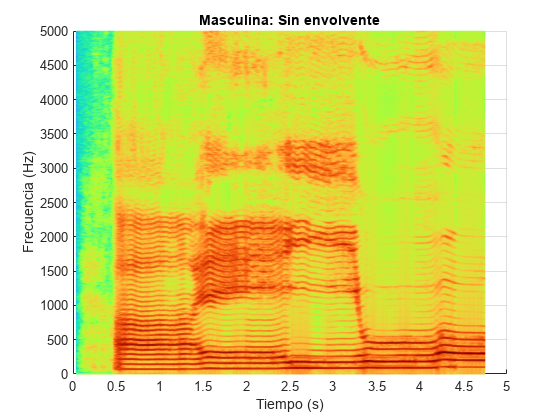

[xa,fs] = audioread('audiom.wav');
xb = xa(:,1);
x = xb(2:length(xb)) -0.625.*xb(1:(length(xb)-1));

t = (0:1/fs:(length(x)-1)*1/fs)';

L = length(x);
WS = 482*7; % 7
DW = 64;
NW = floor((L-WS)/DW)+1;
g = 0.54 + 0.46*cos(2*pi*(0:WS-1)'/WS - pi);
F = (fs*(0:WS/2-1)/WS)*0.6;
X = zeros(WS/2, NW);

for k=1:NW
    n = DW*(k-1)+(1:WS)';
    y = x(n).*g;
    Y = fft(y);
    X(:,k) = 20*log10(abs(Y(1:WS/2)));
end
figure, mesh((DW*(0:NW-1)'+WS/2)/fs,F,X)

view(2)
ylim([0 5000]);
title('Masculina: Sin envolvente')
xlabel('Tiempo (s)')
ylabel('Frecuencia (Hz)')
colormap(turbo)

Esta parte del código genera un espectrograma que representa cómo varía la energía de la señal de audio en diferentes frecuencias a lo largo del tiempo, específicamente enfocado en la representación de la señal de voz masculina

    [xa,fs] = audioread('audiom.wav');
    xb = xa(:,1);
    x = xb(2:length(xb)) -0.625.*xb(1:(length(xb)-1));
    
    L = length(x);
    WS = 512;
    DW = 16;
    NW = floor((L-WS)/DW)+1;
    g = 0.54 + 0.46*cos(2*pi*(0:WS-1)'/WS - pi);
    F = (fs*(0:WS/2-1)/WS);
    X = zeros(1024, NW);
    H = zeros(1024, NW);
    tono = zeros(size(x));
    A=0;
    for k=1:NW
        n = DW*(k-1)+(1:WS)';
        y = x(n).*g;
        Y = fft(y);
        p=20;
        r= zeros(p+1,1);
        for ck=0:p
            r(ck+1)=y(1:(512-ck))'*y((ck+1):512); 
        end
        R=r(1:p);
        r=r(2:p+1);
        for ck=2:p
            R(:,ck)=[R(ck,1);R(1:p-1,ck-1)];
        end
        Q = -inv(R)*r;
        AX = fft(y,2048);
        X(:,k) = abs(AX(1:1024));
        [AH,w]= freqz(1,[1;Q],1024);
        b0 = max(X(:,k))/max(abs(AH));
        X(:,k) = 20*log10(X(:,k));
        H(:,k) = 20*log10(abs(b0*AH));
    end

Esta sección de código esta realizando un análisis por ventanas superpuestas de la señal de audio, aplicando un modelo autorregresivo a cada segmento para estimar su respuesta en frecuencia. Al final del bucle, las matrices `X` y `H` contendrán las representaciones en frecuencia de la señal original y la respuesta en frecuencia del modelo AR para cada ventana de la señal, respectivamente.

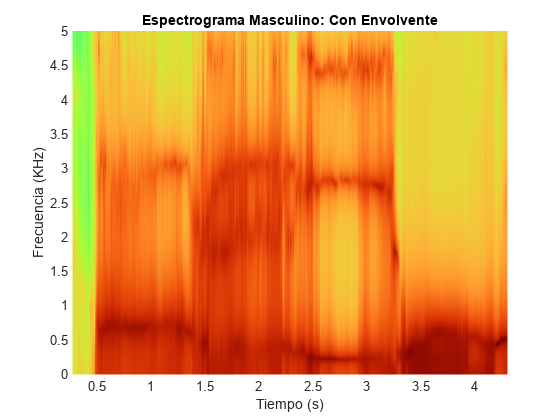

figure, mesh((DW*(0:NW-1)'+WS/2)/fs,w'*6,H)
ylim([0 5]), xlim([0.28 4.3]);
title('Espectrograma Masculino: Con Envolvente')
xlabel('Tiempo (s)')
ylabel('Frecuencia (KHz)')
zlabel('Intensidad (dB)')
view(2)
colormap(turbo)

Esta sección de código crea una representación visual tridimensional del espectrograma de la señal de audio masculina, donde el tiempo, la frecuencia y la intensidad están representados en los ejes x, y, y z respectivamente. La paleta de colores 'turbo' se utiliza para mostrar las variaciones de intensidad a lo largo del tiempo y la frecuencia en el espectrograma.

fs=44100;
% Lectura de las señales de voz masculina y femenina
[yH, fsH] = audioread("audiom.wav",[0.45,4.75]*fs);         % Voz Masculina 
[yM, fsM] = audioread("audiof.wav",[0.8 , 4.2]* fs);       % Voz Femenina

% Frecuencia de muestreo 2 y conversión a un solo canal
fs2 = 8000;
yH = resample(yH, fs2, fsH);
yH = mean(yH, 2);
yM = resample(yM, fs2, fsM);
yM = mean(yM, 2);

WSH = 256*0.5;     % Tamaño de la ventana masculina
WSM = 256*0.5;     % Tamaño de la ventana femenina
L_FFT = 256 * 8;  
p = 20;             
r = zeros(p+1,1);

% UBICACION VOCALES MASCULINAS
AH = 0 * fs2; 
EH = 1 * fs2;
IH = 2 * fs2;
OH = 3   * fs2;
UH = 3.75 * fs2;

% UBICACION VOCALES FEMENINAS
AM = 0 * fs2;
EM = 0.75 * fs2;
IM = 1.5 * fs2;
OM = 2.3 * fs2;
UM = 2.8 * fs2;


% Normalizacion de las señales de voz.

% Señal de voz masculina
y_AH = FcnNorm(yH(AH + (1:WSH))) ; y_EH = FcnNorm(yH(EH + (1:WSH)));
y_IH = FcnNorm(yH(IH + (1:WSH))) ; y_OH = FcnNorm(yH(OH + (1:WSH)));
y_UH = FcnNorm(yH(UH + (1:WSH))) ;
% Señal de voz femenina
y_AM = FcnNorm(yM(AM + (1:WSM))) ; y_EM = FcnNorm(yM(EM + (1:WSM)));
y_IM = FcnNorm(yM(IM + (1:WSM))) ; y_OM = FcnNorm(yM(OM + (1:WSM)));
y_UM = FcnNorm(yM(UM + (1:WSM))) ;

% Calculo de los vectores de tiempo para las señales de voz de cada vocal.

% Señal de voz masculina
t_AH = (0 : length(y_AH) - 1)'/ fs2 ; t_EH = (0 : length(y_EH) - 1)'/ fs2;  
t_IH = (0 : length(y_IH) - 1)'/ fs2 ; t_OH = (0 : length(y_OH) - 1)'/ fs2;  
t_UH = (0 : length(y_UH) - 1)'/ fs2 ;  
% Señal de voz femenina
t_AM = (0 : length(y_AM) - 1)'/ fs2 ; t_EM = (0 : length(y_EM) - 1)'/ fs2;  
t_IM = (0 : length(y_IM) - 1)'/ fs2 ; t_OM = (0 : length(y_OM) - 1)'/ fs2;  
t_UM = (0 : length(y_UM) - 1)'/ fs2 ; 

% Calculo de la envolvente espectral de frecuencia.

% Señal de voz masculina
[Y_AH, H_AH, w_AH] = Envol(y_AH, WSH, L_FFT, p, r);
[Y_EH, H_EH, w_EH] = Envol(y_EH, WSH, L_FFT, p, r);
[Y_IH, H_IH, w_IH] = Envol(y_IH, WSH, L_FFT, p, r);
[Y_OH, H_OH, w_OH] = Envol(y_OH, WSH, L_FFT, p, r);
[Y_UH, H_UH, w_UH] = Envol(y_UH, WSH, L_FFT, p, r);
% Señal de voz femenina
[Y_AM, H_AM, w_AM] = Envol(y_AM, WSM, L_FFT, p, r);
[Y_EM, H_EM, w_EM] = Envol(y_EM, WSM, L_FFT, p, r);
[Y_IM, H_IM, w_IM] = Envol(y_IM, WSM, L_FFT, p, r);
[Y_OM, H_OM, w_OM] = Envol(y_OM, WSM, L_FFT, p, r);
[Y_UM, H_UM, w_UM] = Envol(y_UM, WSM, L_FFT, p, r);


% Aplicación de reconocimiento de voz para las vocales
GrabarAudio(8000,16,2,2,"grb1.wav"); 

Comenzando la grabación...
Grabación finalizada.
    "Audio grabado guardado en "    "grb1.wav"    " exitosamente."



Se realiza una serie de operaciones de procesamiento y análisis de señales de voz masculina y femenina, incluyendo normalización, extracción de segmentos, cálculo de envolventes espectrales y posiblemente grabación de voz para reconocimiento.

% Lectura de la señal grabada
[y, fs] = audioread("grb1.wav");

% Ajuste de la frecuencia de muestreo y conversión a mono
y = resample(y, fs2, fs);
y = mean(y, 2);

% Normalización y reproducción de la señal de voz
y = normalize(y);
sound(y, fs2);

t = (0 : length(y) - 1)'/ fs2; 

% Calculo de la envolvente espectral de la señal de voz.

WS = length(y);
[Y, H, w] = Envol(y, WS, L_FFT, p, r);

Envolvente is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\marti\Downloads\Lab4_Cetina_Diaz_Roa

Change the MATLAB current folder or add its folder to the MATLAB path.


% Calculo del error, por medio de la funcion de correlacion de matlab, 
% entre las señales de voz pre guardadas, con la señal de voz a identificar.

% Error respecto a las señales de voz femeninas.
C(1)   = mean(abs(corr(H, H_AH)));
C(2)   = mean(abs(corr(H, H_EH)));
C(3)   = mean(abs(corr(H, H_IH)));
C(4)   = mean(abs(corr(H, H_OH)));
C(5)   = mean(abs(corr(H, H_UH)));
% Error respecto a las señales de voz femeninas.
C(6)   = mean(abs(corr(H, H_AM)));
C(7)   = mean(abs(corr(H, H_EM)));
C(8)   = mean(abs(corr(H, H_IM)));
C(9)   = mean(abs(corr(H, H_OM)));
C(10)  = mean(abs(corr(H, H_UM)));

% Reconocimiento de voz por medio del coeficiente de correlacion. Entre mas
% parecidas sean las señales la correlacion aumenta (-1 a 1).

maxC = max(C);  % Valor maximo de correlacion de las señales.

if maxC == C(1)
    v = "A" ; g = "Masculino";
    Y1 = Y_AH;
    H1 = H_AH;
elseif maxC == C(2)
    v = "E" ; g = "Masculino";
    Y1 = Y_EH;
    H1 = H_EH;
elseif maxC == C(3)
    v = "I" ; g = "Masculino";
    Y1 = Y_IH;
    H1 = H_IH;
elseif maxC == C(4)
    v = "O" ; g = "Masculino";
    Y1 = Y_OH;
    H1 = H_OH;
elseif maxC == C(5)
    v = "U" ; g = "Masculino";
    Y1 = Y_UH;
    H1 = H_UH;
elseif maxC == C(6)
    v = "A" ; g = "Femenino";
    Y1 = Y_AM;
    H1 = H_AM;
elseif maxC == C(7)
    v = "E" ; g = "Femenino";
    Y1 = Y_EM;
    H1 = H_EM;
elseif maxC == C(8)
    v = "I" ; g = "Femenino";
    Y1 = Y_IM;
    H1 = H_IM;
elseif maxC == C(9)
    v = "O" ; g = "Femenino";
    Y1 = Y_OM;
    H1 = H_OM;
elseif maxC == C(10)
    v = "U" ; g = "Femenino";
    Y1 = Y_UM;
    H1 = H_UM;
end
% Visualización de las envolventes espectrales
figure();
subplot(211)
plot(w, [Y1 H1]);
title(sprintf('Comparación - Vocal: %s', v));
xlabel("Frecuencia [KHz]"), ylabel("Magnitud [dB]");
grid on;

subplot(212)
plot(w_EM, [Y_EM H_EM]);
title(sprintf('Grabación - Vocal: %s', v));
xlabel("Frecuencia [KHz]"), ylabel("Magnitud [dB]");
grid on;

fprintf("Vocal pronunciada: '%s' \n", v);

fprintf("Genero determinado: '%s' \n", g);

**V. Resultados**

La última parte del código analiza una señal de voz grabada, calcula su envolvente espectral y la compara con modelos predefinidos para reconocer la vocal pronunciada en la señal grabada. Además, muestra visualmente la comparación de las envolventes espectrales de la vocal reconocida con la de una vocal femenina específica ("I").

La resolución del problema implica evaluar los niveles de energía y la frecuencia de cruces por cero asociados a cada sonido en el habla, lo que permite caracterizar y distinguir cada uno en la señal de audio. Esto requiere un análisis detallado de la energía y los cruces por cero para cada sonido, ya sea una vocal o consonante. Para lograr esto, se identifican los puntos máximos y mínimos de estas magnitudes y se calcula su promedio, estableciendo un rango óptimo para cada sonido en la señal. Es importante señalar que estos segmentos representan las divisiones por cada letra o sonido en el audio, y se normalizan al ritmo de muestreo necesario para poder analizar el contenido de energía presente en cada segmento.

Estas representaciones permiten observar y comparar diferentes características de las señales de audio procesadas. La superposición de diferentes representaciones proporciona una visión más completa de la señal, mostrando tanto su forma de onda general como aspectos más específicos relacionados con cruces por cero, energía y categorización, lo que puede ser útil para analizar y comprender mejor el contenido de las señales de audio.

**VI. Discusión**

Con el objetivo final de realizar el reconocimiento de voz, se llevaron a cabo varios pasos preliminares y se aplicaron diversos conceptos aprendidos durante la instrucción. La grabación continua de vocales tanto en voz femenina como masculina permitió la obtención de funciones tonales, las cuales fueron utilizadas para derivar las envolventes espectrales. Estos datos sirvieron como base para la creación del espectrograma final, ofreciendo una representación visual precisa de los resultados obtenidos.

Al analizar la información recopilada, se identificaron diferencias notables en los formantes de cada vocal entre las voces masculinas y femeninas. Estos hallazgos fueron fundamentales para la siguiente fase, que involucró el desarrollo de un algoritmo en MATLAB basado en los niveles de energía expresados en Hz para cada formante de cada vocal. Este enfoque permitió una identificación precisa de las vocales pronunciadas, aunque hubo un desafío particular con la vocal "i", donde los picos de los formantes variaban considerablemente, a veces confundiéndose con la "e".

Este problema se asoció específicamente a las vocales "i" y "e" debido a regiones donde las intensidades de energía eran similares, lo que complicaba la correcta clasificación. En contraste, las demás vocales resultaron más fáciles de identificar. Además, se observó que tanto el dispositivo de captura de sonido como la forma de vocalizar afectaban la precisión de la aplicación, destacándose que una buena vocalización y un tono alto mejoraban la exactitud. La presencia de ruido en las grabaciones también influyó en la distorsión de los datos, lo que llevó a la implementación de un filtro en la aplicación con valores sugeridos por el profesor y una frecuencia de muestreo de 8000 Hz.

Para distinguir entre voces masculinas y femeninas, se utilizaron las características únicas de cada tracto vocal, derivadas de un laboratorio que incluía ambos tipos de voz y dependían del tamaño y la fisonomía del hablante. Todos los análisis se realizaron con archivos de audio grabados en condiciones óptimas, utilizando el formato .wav para el tratamiento de los archivos de voz. Se destacó la importancia de la calidad de las señales en los análisis, ya que esta afectaba la precisión de los resultados y los gráficos obtenidos.

El modelado paramétrico y la codificación lineal surgieron como herramientas fundamentales en el análisis y procesamiento de señales, simplificando la comprensión y proporcionando información más clara. Finalmente, se desarrolló un eficiente algoritmo en MATLAB para el reconocimiento de vocales, así como algoritmos para obtener gráficos e información de cada vocal y audio grabado por el grupo. La aplicación exitosa de las herramientas aprendidas en clase fue esencial para un procesamiento de señales adecuado y un análisis congruente con los conocimientos impartidos por el profesor, demostrando la aplicabilidad de las matemáticas y la ingeniería en situaciones cotidianas como el habla y el lenguaje, generando resultados convincentes y asombrosos.

**VII. Conclusiones**

- Las diferencias entre la voz masculina y femenina se reflejan en las señales de audio: las señales de voz masculina tienen una frecuencia fundamental más baja y una distribución de energía en frecuencias más bajas, mientras que las señales de voz femenina tienen una frecuencia fundamental más alta y una distribución de energía en frecuencias más altas.

- Las diferencias del espectro de las vocales pueden ser capturadas por modelos como el análisis mediante filtros autorregresivos (AR), donde se intenta encontrar coeficientes que mejor modelen la señal en el dominio de la frecuencia, reflejando así las características únicas de cada vocal en términos de su contenido espectral.

- Se realizó normalización, extracción de segmentos y cálculo de envolventes espectrales, ya que estas operaciones son esenciales para preparar las señales de voz y extraer características relevantes que pueden ser utilizadas en el análisis y reconocimiento de patrones en el habla, lo cual es crucial en aplicaciones como el reconocimiento de voz y el procesamiento del lenguaje natural, entre otros.

**VIII. Referencias**

[1] Marco Aurelio Alzate. Procesamiento Digital de Señales: Apuntes de Clase